# 2PEM-100A

## `PRACTICE 3_2`

## `Display one of the variables with changed frequency`

`More information:`

- [https://2pem100a.blogspot.com/](https://2pem100a.blogspot.com/)

`More examples:`

- [https://github.com/vasanza/Matlab_Code/tree/Electrical-Systems-Simulation](https://github.com/vasanza/Matlab_Code/tree/Electrical-Systems-Simulation)

- [https://github.com/avbazurt/Simulacion_Sistemas_Electricos](https://github.com/avbazurt/Simulacion_Sistemas_Electricos)

`Dataset:`

- [http://ieee-dataport.org/8630](http://ieee-dataport.org/8630)

Technical information

- Sampling frequency: 4Hz (250mSeg)

**1- Loading a .mat file with 1sample sampling rate / 15min = 1sample / 900seg**

**Data (451x9), donde 451x15min=6765min/60min=112.75horas/24=4.69dias**

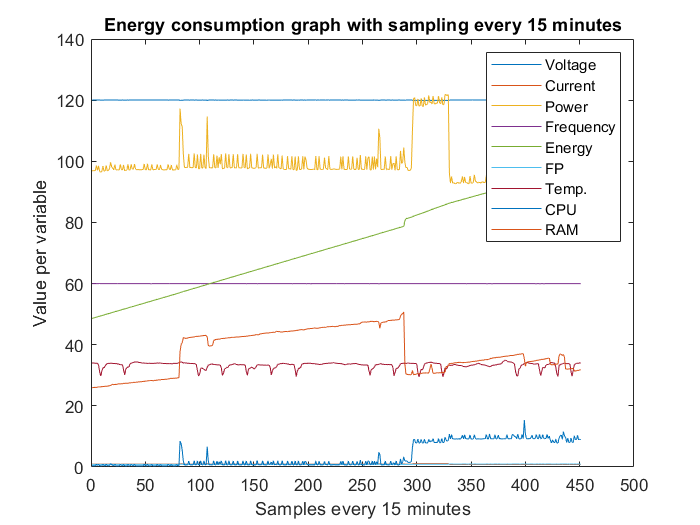

clear;%borra el worskpace
clc;%borra el comand windiw
path=fullfile('./datamean.mat');
data=load(path);
data=struct2cell(data);
data=data{1,1};%table
plot(data);%datos originales
title('Energy consumption graph with sampling every 15 minutes');
legend('Voltage','Current','Power','Frequency','Energy','FP','Temp.','CPU','RAM');

xlabel('Samples every 15 minutes');
ylabel('Value per variable');

# **Example 4: Working with one of the variables**

prompt = 'Select one of the variables (1-9)';
x = input(prompt) %columna para seleccionar la variable

x = 1

variable=data(:,x);
datastats(variable)

ans = struct with fields:
       num: 451
       max: 120.0674
       min: 119.9012
      mean: 120.0236
    median: 120.0337
     range: 0.1661
       std: 0.0345


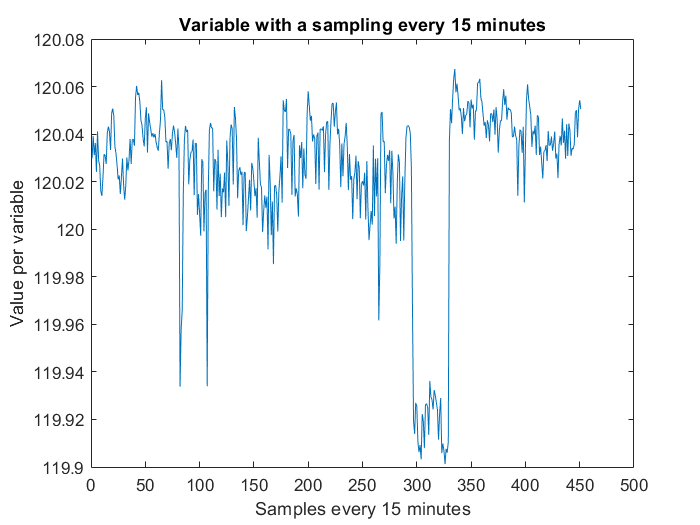


plot(variable);%datos originales
title('Variable with a sampling every 15 minutes');
%legend('Voltage','Current','Power','Frequency','Energy','FP','Temp.','CPU','RAM');

xlabel('Samples every 15 minutes');
ylabel('Value per variable');